clear
close all
clc

addpath(genpath('C:\Program Files\Mosek\11.0\toolbox\r2019b'));
addpath(genpath('.\YALMIP'));

We consider the example from the paper "Robust Control Contraction Metrics: A Convex Approach to Nonlinear State-Feedback H∞ Control".

nx = 2;
nu = 1;
ny = 2;
f = @(x) ([ x(2,:); -x(1,:)-1.5*x(2,:).^2-0.5*x(2,:).^3 ]);
B = [1;0];
H = [0;1];
C = [0,1];
D = 0.1;

nlsys.nx = nx;
nlsys.nu = nu;
nlsys.ny = ny;
nlsys.f = f;
nlsys.g = @(x,u) (B*u);
nlsys.h = @(x,u) (C*x + D*u);

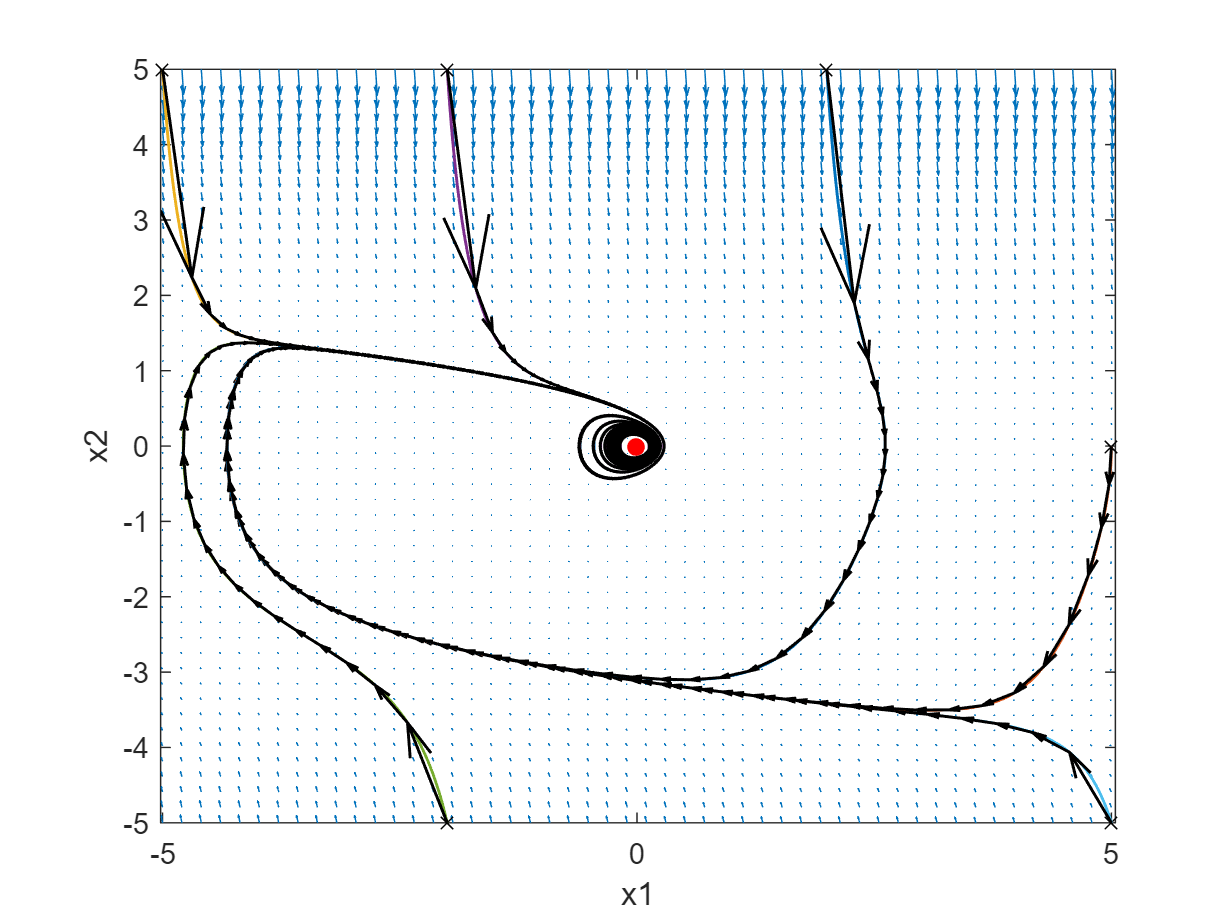

% Find equilibrium points
x_sym = sym('x',[nx,1],'real');
sols = solve(f(x_sym) == 0,x_sym);

% Visualize vector field
xis = linspace(-5,5,5e1);
[x1s,x2s] = meshgrid(xis, xis);
f1s = zeros(length(xis),length(xis));
f2s = zeros(length(xis),length(xis));
for i1=1:length(xis)
    for i2=1:length(xis)
        xi = [x1s(i1,i2);x2s(i1,i2)];
        xdi = f(xi);
        f1s(i1,i2) = xdi(1);
        f2s(i1,i2) = xdi(2);
    end
end


figure
% Plot vector field
quiver(x1s,x2s,f1s,f2s,'AutoScale','on','AutoScaleFactor',1.3)
hold on
% Plot trajectories
x0s = [-5, 5, 5, -2, 2, -2;
        5,-5, 0, -5, 5, 5];
Narr = 100;  % adjust arrow spacing
for i=1:size(x0s,2)
    scatter(x0s(1,i),x0s(2,i),'kx')
    [~,traji] = simRK4(f, x0s(:,i), 100, 1e-3);
    plot(traji(1,:),traji(2,:),'LineWidth',1)
    x1arr = traji(1,1:Narr:end-1);
    x2arr = traji(2,1:Narr:end-1);
    dx1arr = diff(traji(1,1:Narr:end));
    dx2arr = diff(traji(2,1:Narr:end));
    quiver(x1arr, x2arr, dx1arr, dx2arr, 0, 'k', 'filled', ...
           'LineWidth', 1, 'MaxHeadSize', 2);
end
% Plot Equilibrium points
scatter(sols.x1,sols.x2,'ro','filled')
axis tight
xlabel('x1')
ylabel('x2')
xlim([-5,5])
ylim([-5,5])

The system has two equilibrium points: $x^*=(0,0)$, which is unstable, and $x^*=(1,1)$, which is locally asymptotically stable.

We are interest in stabilizing the system at $x^*=(0,0)$.

xeq = zeros(nx,1);

Now we compute the linearized system at the origin

x = sym('x', [nx,1], 'real');
u = sym('u', [nu,1], 'real');
xdot_ = f(x) + B*u

$$xdot\_ = \left(\begin{array}{c} u_{1}+x_{2}\\ -\frac{{x_{2}}^{3}}{2}-\frac{3\,{x_{2}}^{2}}{2}-x_{1} \end{array}\right)$$


nablax = jacobian(xdot_, x)

$$nablax = \left(\begin{array}{cc} 0 & 1\\ -1 & -\frac{3\,{x_{2}}^{2}}{2}-3\,x_{2} \end{array}\right)$$

A_ = subs(nablax, [x;u], [xeq; zeros(nu,1)])

$$A\_ = \left(\begin{array}{cc} 0 & 1\\ -1 & 0 \end{array}\right)$$

A = double(A_);

linSys = ss(A,B,C,D);

We create a local LQR controller to impose as constraint on the differential controller.

Q = eye(nx);
R = eye(nu);
P = are(A,B*inv(R)*B',Q)

P =     1.3522   -0.4142
   -0.4142    1.9123


Klqr_K = -inv(R)*B'*P

Klqr_K =    -1.3522    0.4142


Klqr = @(x) (-inv(R)*B'*P*x);

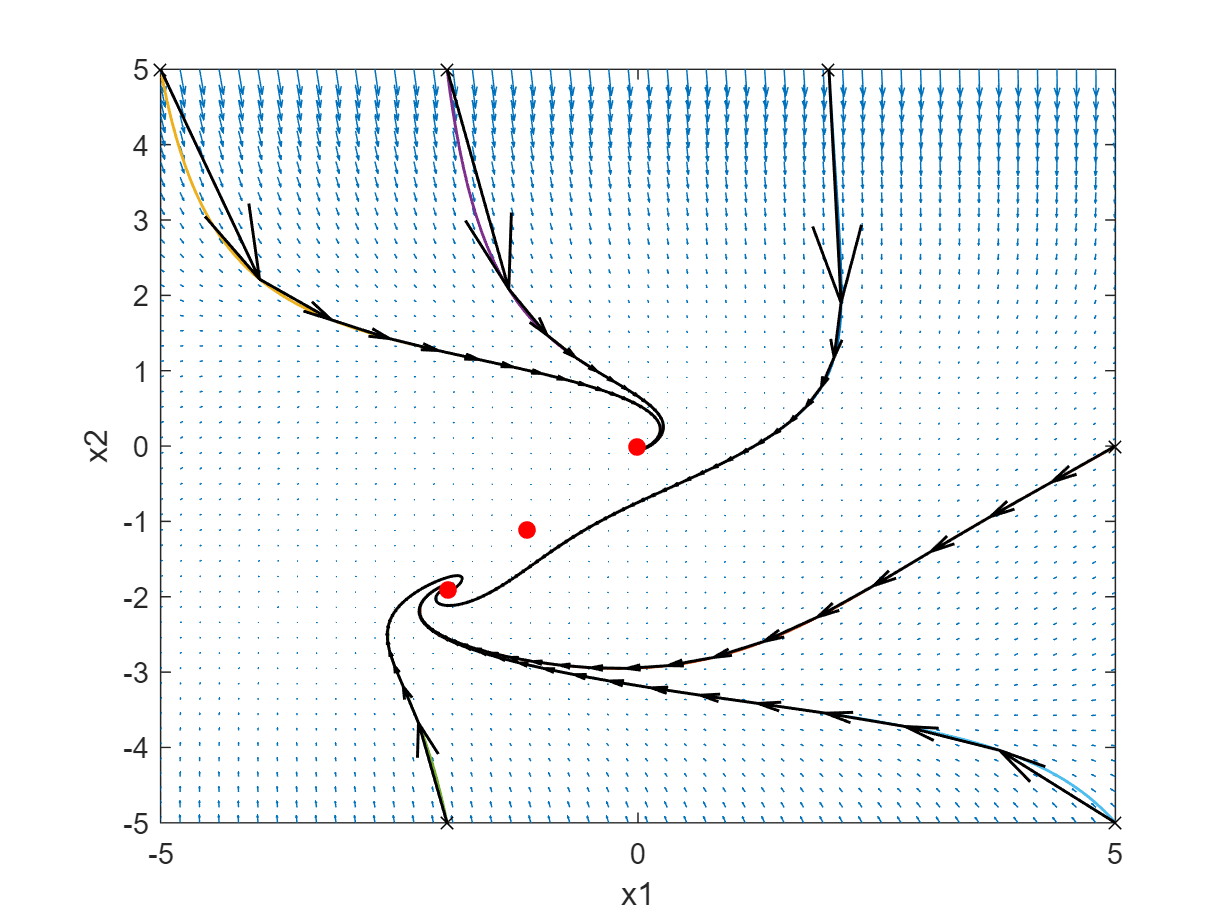

% Find equilibrium points
x_sym = sym('x',[nx,1],'real');
sols = solve(f(x_sym)+B*Klqr_K*x_sym == 0,x_sym);

% Visualize vector field
xis = linspace(-5,5,5e1);
[x1s,x2s] = meshgrid(xis, xis);
f1s = zeros(length(xis),length(xis));
f2s = zeros(length(xis),length(xis));
for i1=1:length(xis)
    for i2=1:length(xis)
        xi = [x1s(i1,i2);x2s(i1,i2)];
        xdi = f(xi)+B*Klqr_K*xi;
        f1s(i1,i2) = xdi(1);
        f2s(i1,i2) = xdi(2);
    end
end


figure
% Plot vector field
quiver(x1s,x2s,f1s,f2s,'AutoScale','on','AutoScaleFactor',1.3)
hold on
% Plot trajectories
x0s = [-5, 5, 5, -2, 2, -2;
        5,-5, 0, -5, 5, 5];
Narr = 100;  % adjust arrow spacing
for i=1:size(x0s,2)
    scatter(x0s(1,i),x0s(2,i),'kx')
    [~,traji] = simRK4(@(xi) (f(xi)+B*Klqr_K*xi), x0s(:,i), 100, 1e-3);
    plot(traji(1,:),traji(2,:),'LineWidth',1)
    x1arr = traji(1,1:Narr:end-1);
    x2arr = traji(2,1:Narr:end-1);
    dx1arr = diff(traji(1,1:Narr:end));
    dx2arr = diff(traji(2,1:Narr:end));
    quiver(x1arr, x2arr, dx1arr, dx2arr, 0, 'k', 'filled', ...
           'LineWidth', 1, 'MaxHeadSize', 2);
end
% Plot Equilibrium points
scatter(sols.x1,sols.x2,'ro','filled')
axis tight
xlabel('x1')
ylabel('x2')
xlim([-5,5])
ylim([-5,5])

Now, we can look for a contraction metric $W$ and a nonlinear (polynomial) differential controller gain $Y(x)$.

yalmip('clear')

x = sdpvar(nlsys.nx,1);

f_sos = f(x);

% Define Y as nu by nx polynomial matrix
ZY = monolist(x,1);
YM = sdpvar(length(ZY)*nu, length(ZY)*nx);
Y = kron(eye(nu),ZY)'*YM*kron(eye(nx),ZY);

ZW = monolist(x(2),2);
WM = sdpvar(length(ZW)*nx,length(ZW)*nx);
W = kron(eye(nx),ZW)'*WM*kron(eye(nx),ZW);

lambda = 1e-2;
nablaf_sos = jacobian(f_sos, x);
dirW = 0;
for i=1:nx
    dirW = dirW + jacobian(W,x(i))*f_sos(i);
end
% Vdot = -dirW + nablaf_sos*W + W*nablaf_sos' -rho*B*B' + 2*lambda*W;
Vdot = -dirW + nablaf_sos*W + W*nablaf_sos' + B*Y + Y'*B' + 2*lambda*W;

% Compact constraint
phi_max = 5;
g = -( -phi_max^2 + x(2).^2);
% Positivstellensatz polynomials
[s1,c1] = polynomial(x,4);

F = [sos( -( Vdot + 1e-6*eye(nx) ) -s1*g*eye(nx) )]; % Vdot < 0
% F = [sos( -( Vdot + 1e-6*eye(nx)) )]; % Vdot < 0

% Uniform polynomial bounds on Y(x)
% Zb = monolist(x,1);
Zb = [1];
ubM = sdpvar(length(Zb)*nx,length(Zb)*nx);
ubound = kron(eye(nx),Zb)'*ubM*kron(eye(nx),Zb);
lbM = sdpvar(length(Zb)*nx,length(Zb)*nx);
lbound = kron(eye(nx),Zb)'*lbM*kron(eye(nx),Zb);
F = [F, sos( -( W-ubound ) )];
F = [F, sos( W-lbound )];
% F = [F, sos(ubound-lbound), sos(ubound), sos(-lbound)];
F = [F, sos(ubound-lbound-1e-6*eye(nx)), sos(ubound), sos(lbound)];

% Robuts CCM constraint
% beta = sdpvar(1,1);
beta = 1/0.9^2;
F = [F, sos([dirW-nablaf_sos*W-W*nablaf_sos'-B*Y-Y'*B'-beta*(H*H'),W'*C'+Y'*D'; ...
             C*W+D*Y, eye(1)] -s1*g*eye(nx+1))];

% F = [F, W >= 1e-6*eye(nx)];
F = [F, sos(W)];

% Local equivalence with LQR controller
% F = [F, replace(rho,x,xeq) == 2*inv(R)];
F = [F, replace(Y,x,xeq) == -inv(R)*B'];
F = [F, replace(W,x,xeq) == inv(P)];

% F = [F, sos(s1), beta >= 0];
F = [F, sos(s1)];

ops = sdpsettings('solver','mosek','verbose',1);
% solvesos(F, -beta, ops, [YM(:);W(:);c1(:);beta]);
solvesos(F, norm(WM(:),1) + norm(YM(:),1), ops, [YM(:);WM(:);c1(:);ubM(:);lbM(:)]);

-------------------------------------------------------------------------
YALMIP SOS module started...
-------------------------------------------------------------------------
Detected 116 parametric variables and 2 independent variables.
Detected 4 linear inequalities, 2 equality constraints and 0 LMIs.
Using kernel representation (options.sos.model=1).
Initially 9 monomials in R^2
Newton polytope (0 LPs).........Keeping 9 monomials (0sec)
Finding symmetries..............Found no symmetries (0sec)
Initially 3 monomials in R^1
Newton polytope (0 LPs).........Keeping 3 monomials (0.015625sec)
Finding symmetries..............Found no symmetries (0sec)
Initially 3 monomials in R^1
Newton polytope (0 LPs).........Keeping 3 monomials (0sec)
Finding symmetries..............Found no symmetries (0sec)
Initially 9 monomials in R^2
Newton polytope (0 LPs).........Keeping 9 monomials (0sec)
Finding symmetries..............Found no symmetries (0sec)
Initially 3 monomials in R^1
Newton polytope (0


% Define Y as nu by nx polynomial matrix
% rho = clean(Zhro'*value(rhoM)*Zhro, 1e-2); sdisplay(rho)
Y = clean(kron(eye(nu),ZY)'*value(YM)*kron(eye(nx),ZY), 1e-3); sdisplay(Y)

ans = 1×2 cell array
    {'-1+0.725940303877*x(1)+0.668917855248*x(2)-488.991442898*x(2)^2-313.818574551*x(1)^2-15.2730595525*x(1)*x(2)'}    {'1.61160395294*x(1)-2.45684103202*x(2)-38.3507585684*x(2)^2-5.6636470668*x(1)^2+1.80088298861*x(1)*x(2)'}



W = kron(eye(nx),ZW)'*value(WM)*kron(eye(nx),ZW); sdisplay(W)

ans = 2×2 cell array
    {'0.792096583738-2.67216371302*x(2)+15.2478226011*x(2)^2-0.428803625495*x(2)^3-0.00865779258311*x(2)^4'}    {'0.171572875254-1.78813184618*x(2)+4.60558374081*x(2)^2+0.0177604568827*x(2)^3-0.0029152217659*x(2)^4'   }
    {'0.171572875254-1.78813184618*x(2)+4.60558374081*x(2)^2+0.0177604568827*x(2)^3-0.0029152217659*x(2)^4'}    {'0.560096865716+0.0221560819228*x(2)+2.87323052151*x(2)^2+0.0842519286003*x(2)^3+0.00956264417619*x(2)^4'}



beta = value(beta); sdisplay(sqrt(1/beta))

0.9


Transform results into MATLAB functions

var_strs = cell(1,nx);
for i=1:nx
    var_strs{i} = ['x(' num2str(i) ')'];
end
Y_f = ypolymat2fun(sdisplay(Y), var_strs);
W_f = ypolymat2fun(sdisplay(W), var_strs);
dW_fs = cell(1,nx);
for i=1:nx
    dW_fs{i} = ypolymat2fun(sdisplay(jacobian(W, x(i))), var_strs);
end
dW_f = @(x,i) ( dW_fs{i}(x) );

dK = @(x) ( Y_f(x)/W_f(x) );

Test the differential controller.

- 
$$\delta K(0) = K_{lqr}$$


assert(norm(dK(zeros(nx,1)) - Klqr_K) < 1e-4, ...
       'Local controller is not equal to LQR design');

assert(norm(W_f(zeros(nx,1)) - inv(P)) < 1e-4, ...
       'Local contraction metric is not equal to LQR Lyapunov matrix');

dyn = @(x,u) ( f(x)+B*u );

tf = 7;               % Final time
dt = 1e-2;             % Step size
x0 = [1.92;0.78];          % Initial condition
% x0 = [0.01;0.01];          % Initial condition

% Initialize geodesic configuration
% config = geodesicConfig(4, 15, nx, W_f, dW_f);
config = geodesicConfig(1, 15, nx, W_f, dW_f);
params = geodesicParams(config, xeq, x0);
xccm0 = params.c0;

[~,xs_lqr] = simRK4(dyn, {x0,[]}, tf, dt, @(x,xk) ({Klqr_K*x, []}));
[ts,xs_ccm] = simRK4(dyn, {x0,xccm0}, tf, dt, @(x,xk) ( Kccm(config,dK,xeq,x,xk) ));

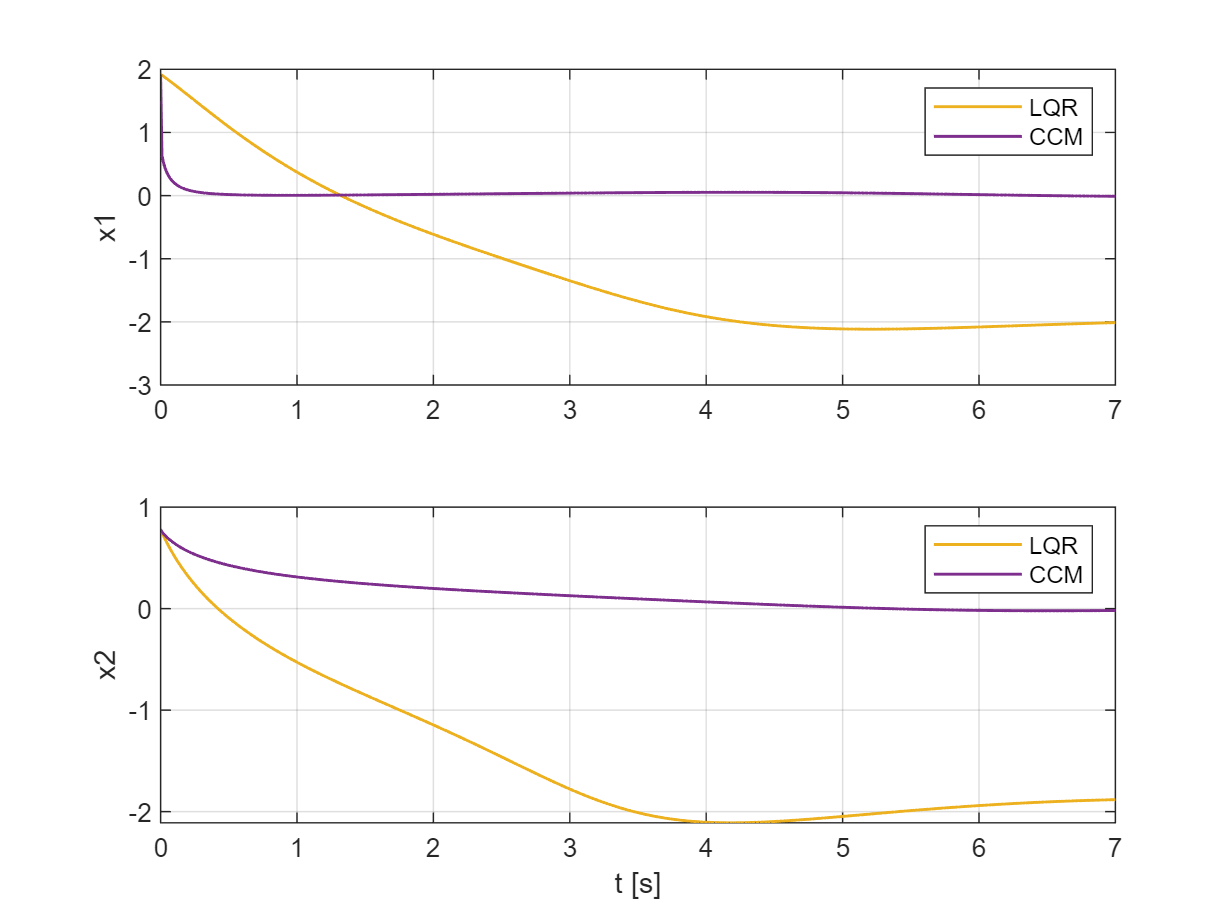

figure
subplot(nx,1,1)
plot(ts,xs_lqr(1,:),'LineWidth',1,'Color',[0.9290 0.6940 0.1250])
hold on
plot(ts,xs_ccm(1,:),'-','LineWidth',1,'Color',[0.4940 0.1840 0.5560])
grid on
ylabel('x1')
% ylim([0,6])
legend('LQR', 'CCM')
subplot(nx,1,2)
plot(ts,xs_lqr(2,:),'LineWidth',1,'Color',[0.9290 0.6940 0.1250])
hold on
plot(ts,xs_ccm(2,:),'-','LineWidth',1,'Color',[0.4940 0.1840 0.5560])
grid on
ylabel('x2')
% ylim([0,6])
legend('LQR', 'CCM')
xlabel('t [s]')

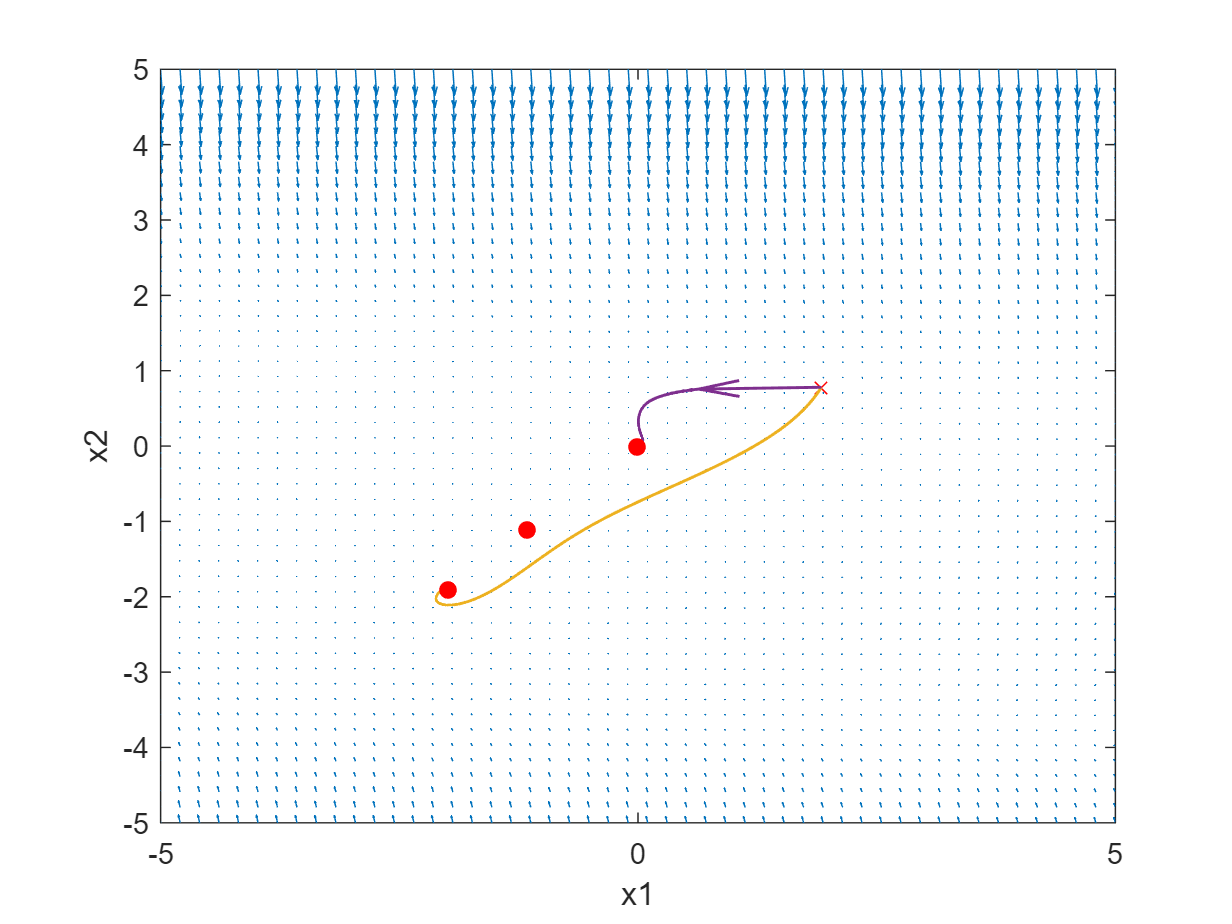

% % Find equilibrium points
% x_sym = sym('x',[nx,1],'real');
% sols = solve(f(x_sym) == 0,x_sym);

% Visualize vector field
xis = linspace(-5,5,5e1);
[x1s,x2s] = meshgrid(xis, xis);
f1s = zeros(length(xis),length(xis));
f2s = zeros(length(xis),length(xis));
for i1=1:length(xis)
    for i2=1:length(xis)
        xi = [x1s(i1,i2);x2s(i1,i2)];
        xdi = f(xi);
        f1s(i1,i2) = xdi(1);
        f2s(i1,i2) = xdi(2);
    end
end

figure
% Plot vector field
quiver(x1s,x2s,f1s,f2s,'AutoScale','on','AutoScaleFactor',1.3)
hold on

% Plot controlled trajectories
scatter(x0(1),x0(2),'rx')

Narr = 1;  % adjust arrow spacing

plot(xs_lqr(1,:),xs_lqr(2,:),'LineWidth',1,'Color',[0.9290 0.6940 0.1250])
x1arr = xs_lqr(1,1:Narr:end-1);
x2arr = xs_lqr(2,1:Narr:end-1);
dx1arr = diff(xs_lqr(1,1:Narr:end));
dx2arr = diff(xs_lqr(2,1:Narr:end));
quiver(x1arr, x2arr, dx1arr, dx2arr, 0, 'filled', 'Color', [0.9290 0.6940 0.1250], ...
       'LineWidth', 1, 'MaxHeadSize', 5, 'AutoScale','on','AutoScaleFactor',2.0);

plot(xs_ccm(1,:),xs_ccm(2,:),'LineWidth',1,'Color',[0.4940 0.1840 0.5560])
x1arr = xs_ccm(1,1:Narr:end-1);
x2arr = xs_ccm(2,1:Narr:end-1);
dx1arr = diff(xs_ccm(1,1:Narr:end));
dx2arr = diff(xs_ccm(2,1:Narr:end));
quiver(x1arr, x2arr, dx1arr, dx2arr, 0, 'filled', 'Color', [0.4940 0.1840 0.5560], ...
       'LineWidth', 1, 'MaxHeadSize', 5, 'AutoScale','on','AutoScaleFactor',2.0);
% plot(xs_ccm(1,:),xs_ccm(2,:),'LineWidth',1,'Color',[0.4940 0.1840 0.5560])

% Plot Equilibrium points
scatter(sols.x1,sols.x2,'ro','filled')
axis tight
xlabel('x1')
ylabel('x2')
xlim([-5,5])
ylim([-5,5])